fname = 'Fig1h_kymo_all_tracks_global_ringtype_iMedFilt_VerCINI data.csv';
data= importdata(fname);

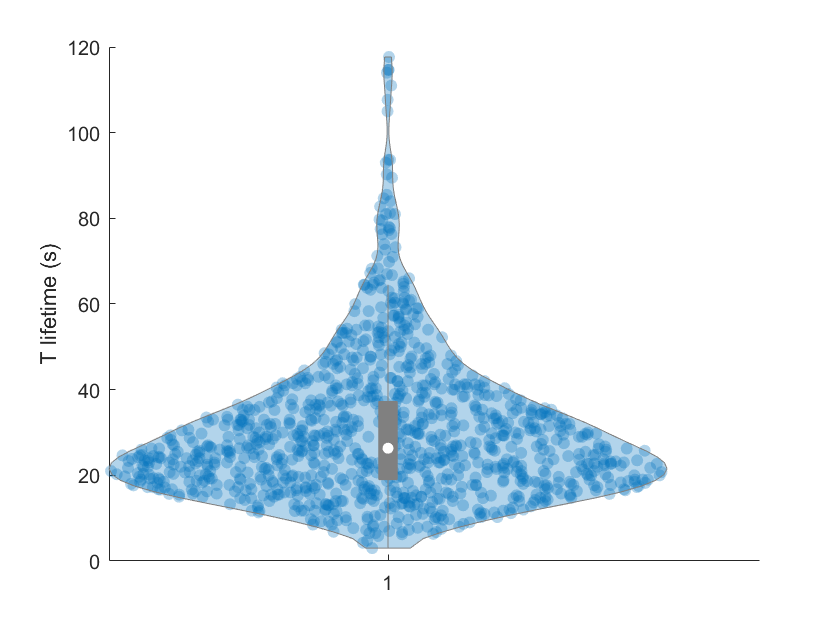

T=abs(data.data(:,2));
S=abs(data.data(:,3));
Diam=data.data(:,7);
isNascent=logical(data.data(:,8));

%keep only the nascent population
T=T(isNascent);%nascent
S=S(isNascent);
Diam=Diam(isNascent);

figure;
violinplot(T);
ylabel('T lifetime (s)');

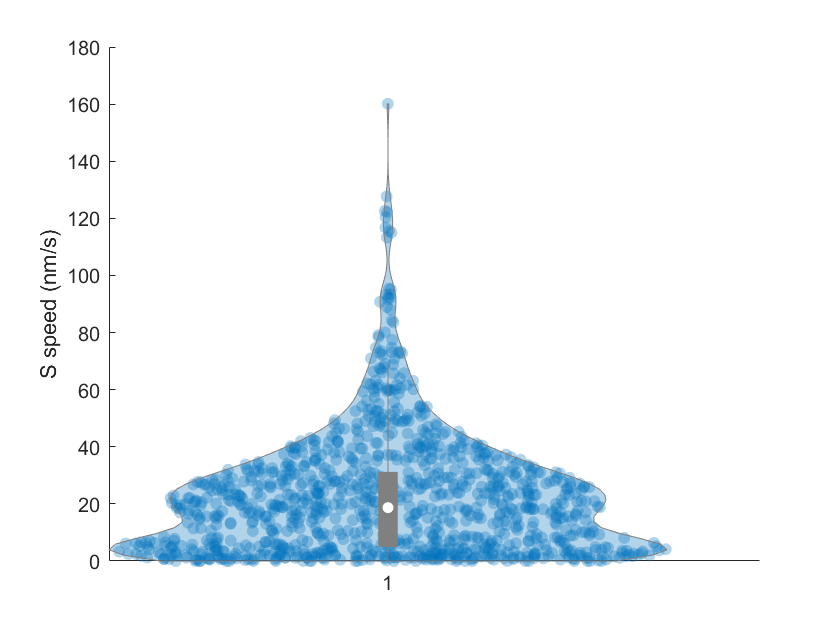


figure;
violinplot(S);
ylabel('S speed (nm/s)')

nascentTracks=table;
nascentTracks.T=T;
nascentTracks.S=S;
nascentTracks.Diam=Diam;
save("nascentTrackData.mat","T","S","Diam","nascentTracks");

nTrackData=numel(T);
TSmat = [T,S];
nTrackKymoAvg=10;
nId=poissrnd(nTrackKymoAvg)

nId = 7

bootId=randi(nTrackData,nId,1)

bootId =          360
         355
        1054
         505
         797
         715
         849


trackBootstrapped=TSmat(bootId,:)

trackBootstrapped =    19.7500   24.6835
   61.0000   18.1148
   25.5000   27.4020
   20.0000    5.6875
   14.7500   48.4746
   36.7500    0.8844
   20.7500   46.9880


Above code outlines approach for resampling of the real data to generate ground truth for artificial kymographs

Now test the simulator implementation

nTrackKymoAvg=10;
trackBootstrapped=genSimTrackTS(nascentTracks,nTrackKymoAvg)

bootId =          471
         748
         278
          31
        1011
        1062
         831
        1055
         520
         137


trackBootstrapped = 12×3 table
      T         S        Diam 
    ______    ______    ______

    8.6667      32.5    936.63
    34.667    15.625    844.97
      33.5    0.9701    860.72
         8    73.125    1071.4
     28.25    10.929    945.97
        19     48.75    899.96
       6.5      92.5    905.76
        34    14.816     854.7
       105    2.4762    956.69
        46    16.956    939.07
      40.5    4.0123    955.56
        54    26.782    844.04


%save('exemplarKymoTrack_single.mat','trackBootstrapped');